Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# Monte-Carlo pricing kernel (Section 10.8)

Volker Ziemann, 211116, CC-BY-SA-4.0

In this example we evaluate the path integral for the pricing kernel using Monte-Carlo simulation. In this particular version we create the sample paths by filling the coordinates of the intermediate points with uniformly distributed random numbers.

Initially we set the parameters of the simulation such as the risk-free rate $r_f$, the volatility $\sigma$, the time $t$, and the number of slices $N$. 

rf=0.03;              % 3 % risk-free rate 
sigma=0.3;            % 30 % volatility per year
rfhat=rf-0.5*sigma^2; % for convenience
t=1;                  % 1 year
N=6;                  % number of time slices
dt=t/N;               % time step between slices
tic                   % start the timer

With the following selection box we can choose the method by how the paths used to evaluate the integral are generated. We also start the timer with the command `tic`.

path_generation="Metropolis"

path_generation = "Metropolis"

tic 

And now we define the $N_{path}$ sample paths by filling an $N\times N_{path}$ array with uniformly distributed random numbers.  Note that the different path generation algorithms use different number of paths.

if path_generation=='Uniformly distributed'
  Npath=20000000;                      % number of sample paths
  x=-4*sigma+8*sigma*rand(N,Npath);    % each row describes a trajectory 
elseif  path_generation=='Metropolis'
  Npath=100000;                        % number of sample paths
  h=@(x)exp(-x.^2/(2*(2*sigma)^2));    % for Metropolis-Hastings
  x0=0.01; beta=3*sqrt(sigma^2*dt);
  y=metropolis3(h,beta,1000,x0);       % 1000 iteration burn-in
  x=metropolis3(h,beta,Npath*N,y(1000));
  x=reshape(x,[N,Npath]); 
elseif path_generation=='Random walk'
  Npath=100000;                        % number of sample paths
  x=2*randn(N,Npath)*sigma/sqrt(N);    % generate random steps
  x=cumsum(x,1);                       % and add them up to a walk
end

In the following lines we evaluate $e^{S_{BS}}$ with $S_{BS}$ given by in Equation 10.62. In` term1` we evaluate the sum over all intermediate points whereas `term2` contains  the contribution from the starting poinf $x_0=0$ and the constant term with $r_f$. The result of the calulation eSBS is an array the contains the value of the path integral for each of the $N_{path}$ paths.

term1=sum((x(2:end,:)-x(1:end-1,:)+dt*rfhat).^2,1);  % all intermediate points
term2=(x(1,:)+dt*rfhat).^2;                          % from start to first                    % from start to first
eSBS=exp(-(term1+term2)/(2*dt*sigma^2));

Since `term1` and `term2` are rather large arrays we clear them from the workspace.

clear term1 term2    % free memory

We now determine the range of end coordinates that actiually appear, split that range into steps of $\sigma/5$ and define the x-axis of the plot as `xx`.

ix=round(x(end,:)/(sigma/5));   % bins of the final position of paths
ixmin=min(ix); ixmax=max(ix);   % range
xx=(ixmin:ixmax)*sigma/5;       % points on which to evaluate the path integral

Then we initialize the `path_integral, `which is the defined on each of the final positions `xx`, to zero and loop over all paths in order to add $e^{S_{BS}}$ to the bin of the final position.

path_integral=zeros(1,ixmax-ixmin+1);
for k=1:Npath
  ipos=ix(k)-ixmin+1;
  path_integral(ipos)=path_integral(ipos)+eSBS(k);
end

In the next code snippet we normalize the path_integral to unity and stop the timer.

i0=(xx(2)-xx(1))*sum(path_integral); % normalize
path_integral=exp(-rf*t)*path_integral/i0; 
toc

Elapsed time is 0.173512 seconds.


Finally, we define the analytically calculated pricing kernel from equation 10.22 as the anonymous function pBS() and plot both the numerically evaluated path_integral and pBS on the same axis.

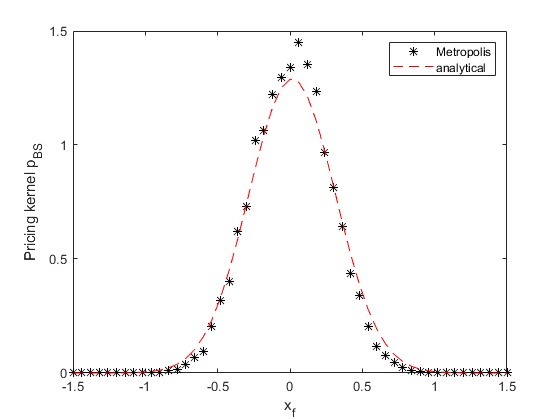

pBS=@(xf)exp(-rf*t-((xf+t*rfhat).^2)/(2*t*sigma^2))/sqrt(2*pi*t*sigma^2); 
plot(xx,path_integral,'k*',xx,pBS(xx),'r--') ; xlim([-1.5,1.5])
xlabel('x_f'); ylabel('Pricing kernel p_{BS}')
legend(path_generation,'analytical'); 

beep

## Appendix

The function `metropolis3()` receives as input a function `f`, the look-around factor $\beta$, the number `nmax` of random number to generate, and a starting value `x0`. It returns an nmax random numbers, drawn form the distribution `f`, in an array `x`. The details are discussed in Section 10.7. 

function x=metropolis3(f,beta,nmax,x0)
   x=zeros(1,nmax);
   x(1)=x0;
   fx=f(x0);
   for k=1:nmax-1       
        y=x(k)+beta*(2*rand-1);  % new candidate
        fy=f(y);
        alpha=fy/fx;         % check if new is better
        if (alpha>1)         % accept, if better
            x(k+1)=y;
            fx=fy;
        else                 % here alpha is smaller than unity
            u=rand;          % get random number
            if (alpha>u)     % compare with random number u
                x(k+1)=y;    % also accept, if larger than u
                fx=f(y);
            else
                x(k+1)=x(k); % else re-use old value
            end
        end
    end
end